# **JacobiSC**

[Jacobi elliptic function sc](https://dlmf.nist.gov/22)

## Definition


$$\mathrm{sc}\left(x\left|m\right.\right)\equiv \frac{\textrm{sn}\left(x\left|m\right.\right)}{\mathrm{cn}\left(x\left|m\right.\right)}$$



$$\mathrm{sc}\left(x,k\right)\equiv \mathrm{sc}\left(x\left|k^2 \right.\right)$$


where *m *is the parameter, *k *is the modulus, and cn and sn are Jacobi elliptic functions function.

Domain: $-\infty <x<\infty$, $-\infty <m<\infty$. For the specified domain, the  codomain of sc is the set of real numbers.

Basic features:

$\mathrm{sc}\left(x+2K\left(m\right)\left|m\right.\right)=\mathrm{sc}\left(x\left|m\right.\right)$  (periodic) ,  $\mathrm{sc}\left(-x\left|m\right.\right)=-\mathrm{sc}\left(x\left|m\right.\right)$ (odd)

Special values:


$$\mathrm{sc}\left(0\left|m\right.\right)=0$$


$\mathrm{sc}\left(x\left|0\right.\right)=\mathrm{tan}\;x$,  $\mathrm{sc}\left(x\left|1\right.\right)=\mathrm{sinh}\;x$

Identities:


$$\mathrm{sc}\left(x\left|m\right.\right)=\mathrm{sd}\left(x\sqrt{m}\left|m^{-1} \right.\right)/\sqrt{m}$$


## Syntax

Y = JacobiSC(X,K)

y = jsc(x,k)

Y = mJacobiSC(X,M)

y = mjsc(x,m)

## Description

Y = JacobiSC(X,K) returns the Jacobi elliptic function $\mathrm{sc}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **JacobiSC** is the wrapper function which calls the functions **jsc** element-wise via the function **ufun2**.

y = jsc(x,k) returns the Jacobi elliptic function $\mathrm{ds}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed. **jsc** calls the functions **sncndn **for calculation of$\mathrm{sc}\left(x,k\right)$ .

Y = mJacobiSC(X,M) returns the Jacobi elliptic function $\mathrm{sc}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mJacobiSC** is the wrapper function which calls the function **mjsc** element-wise via the function **ufun2**.

y = mjsc(x,m) returns the Jacobi elliptic function $\mathrm{sc}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed.  **mjsc** calls the functions **sncndn **for calculation of $\mathrm{sc}\left(x\left|m\right.\right)$ .

**sncndn **implements the AGM transformation for simultaneously  computation of the functions *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

## **Numerical Examples**

**Salar input**

format long
k = 0.5; 
x = 0.5;
[jsc(x,k), JacobiSC(x,k), mjsc(x,k^2), mJacobiSC(x,k^2)]

ans =    0.539903156723383   0.539903156723383   0.539903156723383   0.539903156723383


Accuracy

fprintf('%.16g\n',jsc(3,5))

0.1540037163903525


% Maple 0.1540037163903522_67

[MATLAB example](https://www.mathworks.com/help/symbolic/mupad_ref/jacobisc.html)

disp(mJacobiSC([2 1 -3],[1 2 3]))

   3.626860407847019   0.907683221404946   0.707095700815335



fprintf('%.16g\n',mjsc(3,5))

0.03115989432717164


% MATLAB 0.03115989432717158_1127518352857409


Identities

x=2;
m = 0.12; % m > 0
disp(mjsc(x,m)-1/sqrt(m)*mjsd(x*sqrt(m),1/m))

    -4.440892098500626e-16



**Vector input**

X=[1 2 3 4];
disp(JacobiSC(X,0)-tan(X))

   1.0e-15 *

  -0.222044604925031                   0                   0  -0.222044604925031



X=[1 2 3 4];
disp(JacobiSC(X,1)-sinh(X))

   1.0e-14 *

   0.022204460492503  -0.044408920985006                   0   0.355271367880050



m = 0.12; 
disp(mJacobiSC(X,m)-mJacobiSD(X*sqrt(m),1/m)/sqrt(m))

   1.0e-15 *

   0.444089209850063  -0.444089209850063  -0.555111512312578                   0



**Matrix input**

X=[1 2; 3 4];
disp(JacobiSC(X,1)-sinh(X))

   1.0e-14 *

   0.022204460492503  -0.044408920985006
                   0   0.355271367880050



M = [1 2; 0.2 0.3]; 
disp(mJacobiSC(X,M)-mJacobiSD(X.*sqrt(M),1./M)./sqrt(M))

   1.0e-16 *

                   0                   0
  -0.555111512312578                   0



## **Graphs **

**Example 1**

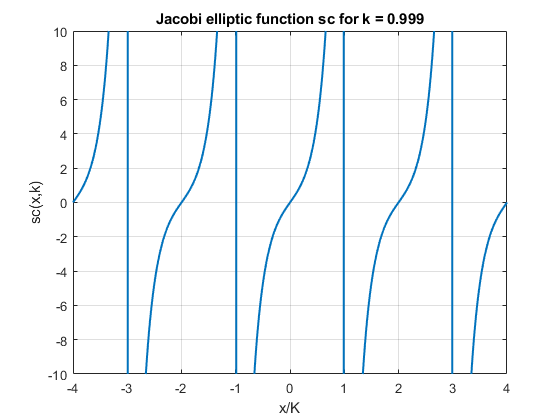

figure
x=-4:0.01:4;
k = 0.999;
K = elK(k);
plot(x,JacobiSC(x*K,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('sc(x,k)')
ylim([-10 10])
title(sprintf('Jacobi elliptic function sc for k = %g',k))
grid on

**Example 2**

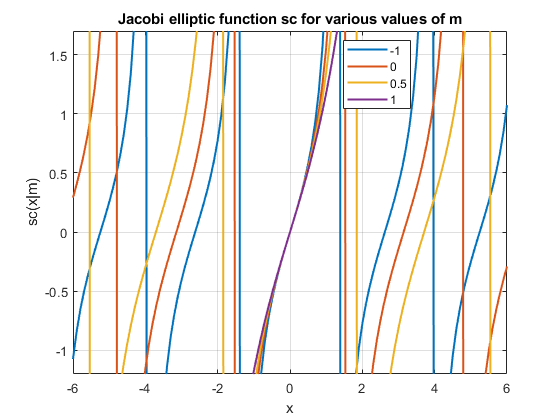

figure
X = -6:0.1:6;
M = [-1,0,0.5,1];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiSC(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1.2 1.7])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Jacobi elliptic function sc for various values of m')
xlabel('x')
ylabel('sc(x|m)')

**Example 3**

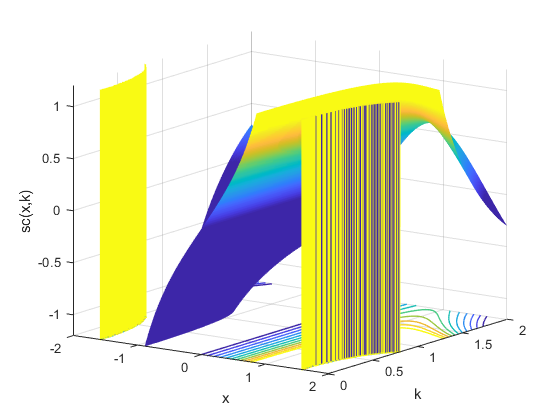

figure
x=-2:0.01:2;
k=0:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiSC(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -1.2;
hc.LineWidth = 1;
hc.LevelList = 0:0.1:1;
caxis([0 1])
view([35 15]);
xlabel('x')
ylabel('k')
zlabel('sc(x,k)')
zlim([-1.2 1.2])
grid on

**Example 4**

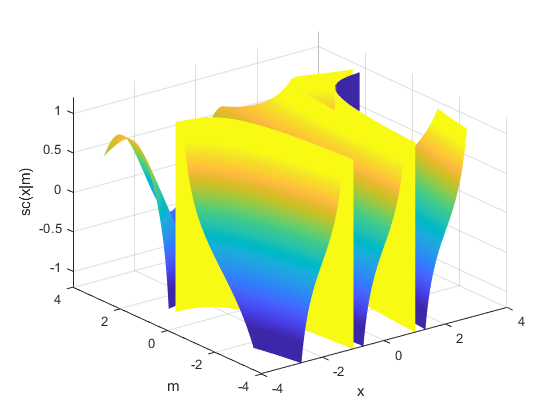

figure
x=-3:0.01:3;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
surface(X,M,mJacobiSC(X,M),'EdgeColor','none')
view(3)
caxis([-1 1])
xlabel('x')
ylabel('m')
zlabel('sc(x|m)')
zlim([-1.2 1.2])
grid on

**Example 5**

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobisd.html)

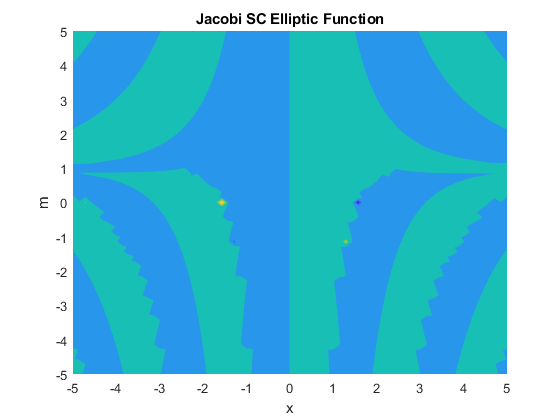

figure
f = @(x,m)mJacobiSC(x,m);
fcontour(f,'Fill','on') %,'LevelList',-3:0.1:3,'MeshDensity',200)
title('Jacobi SC Elliptic Function')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerische Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also